# Analysis 1

side by side gem vs cdt1 in different cycling conditions

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C184_data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

conditions = {
    'induce no release',7,3:7,1:4;
    'no induce release',7,8:11,1:4;
};

S = loadData_C184(conditions, dataDir);


**Compare histograms of Cdt1 no release**

conds = [2 1];
 figure('units','inches','pos',[0 0 4 4]), hold on
for i=1:length(conds)
    condition=conds(i);
    trunc = 10;
    yval = 'FarRed1';
    
    gateVals = {'FarRed1'};
    rangeVals = {[2^0 2^Inf]};
    
   
    
    ydata = log2(S(condition).(yval)); %.*S(condition).area);
    
    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(4,16,100);
    
    [N,~] = histcounts(ydata,edges,'Normalization','pdf');
    plot(edges(2:end),N,'Linewidth',2);
    num_cells = length(ydata)
end

num_cells = 22350

num_cells = 26486

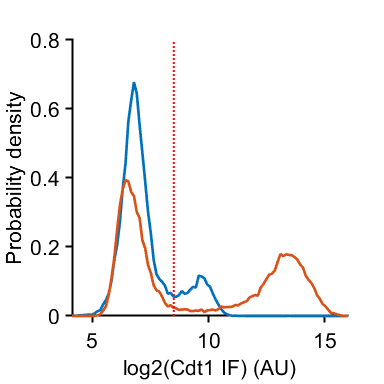

vline(8.5)
ylabel('Probability density')
xlabel('log2(Cdt1 IF) (AU)')
hold off
axis square
print_pdf(['F:\Data\C-Cdt1\Figures\Dryad\Scripts\Cdt1-starve\C184\Figs\cdt1hist.pdf'])